功能说明：Kalman滤波用在一维温度数据测量系统中

N：采样点的个数，时间单位是秒，每秒采样一次，假设行了2分钟的测量

CON：室内温度的理论值

N   = 120; 
CON = 25; 

对状态和测量初始化

Xexpect：期望的温度是恒定的25℃，但真实温度不可能会这样的

X：房间各时刻真实温度值，即为理论值加上受过程噪声影响而产生的波动

Xkf：Kalman滤波器处理的状态，也叫估计值

Z：温度计测量值

Xexpect = CON * ones(1, N);
X       = zeros(1, N);
Xkf     = zeros(1, N);
Z       = zeros(1, N);
P       = zeros(1, N);

赋初值

X(1)：初始房间温度（℃）

P(1)：初始值的协方差

Z(1)：初始测温度量值（℃），可以作为滤波器的初始估计状态

X(1)    = 25.1;
P(1)    = 0.01;
Z(1)    = 24.9;
Xkf(1)  = Z(1);

噪声，方差决定噪声的大小

Q：过程噪声的方差（比如与外界空气交换引起的过程噪声）

R：测量值的方差（假设温度计精度±0.5℃，从出厂说明书上查到方差是 0.25）

W：过程噪声

V：观测噪声

Q       = 0.01;
R       = 0.25;
W       = sqrt(Q) * randn(1, N);
V       = sqrt(R) * randn(1, N);

系统矩阵，本系统状态为一维

F：状态转移矩阵

G：噪声驱动矩阵

H：观测矩阵

F       = 1;
G       = 1;
H       = 1;
I       = eye(1);

模拟房间温度和测量过程，并滤波

for k = 2: N

第一步：随时间推移，房间真实温度波动变化

k时刻房间的真实温度，对于温度计来说，这个真实值是不知道的，但它的存在又是客观事实，要深刻领悟这个计算机模拟过程

    X(k) = F * X(k-1) + G * W(k-1);

第二步：随时间推移，获取实时数据

温度计对k时刻房间温度的测量，Kalman滤波是站在温度计角度进行的，它不知道此刻真实状态X(k)，只能利用本次则量值Z(k)和上一次估计值Xkf(k)来做处理，其目标是最大限度地降低测量噪声R的影响，尽可能地逼近X(k)，这也是Kalman滤波目的所在

    Z(k) = H * X(k) + V(k);

第三步：Kalman滤波

有了k时刻的观测Z(k)和k-1时刻的状态，那么就可以进行滤波了。

X_pre：状态预测

P_pre：协方差预测

Kg：Kalman增益

e：新息

Xkf(k)：状态更新

P(k)：协方差更新

    X_pre  = F * Xkf(k-1);
    P_pre  = F*P(k-1)*F' + Q;
    Kg     = P_pre * inv(H*P_pre*H' + R);
    e      = Z(k) - H*X_pre;
    Xkf(k) = X_pre + Kg*e;
    P(k)   = (I-Kg*H) * P_pre;
end

计算误差

Err_Messure：测量值与真实值之间的偏差

Err_Kalman  ：估计与真实值之间的偏差

Err_Messure = zeros(1, N);
Err_Kalman  = zeros(1, N);
for k = 1: N
    Err_Messure(k) = abs(Z(k) - X(k));
    Err_Kalman(k)  = abs(Xkf(k) - X(k));
end

画图显示

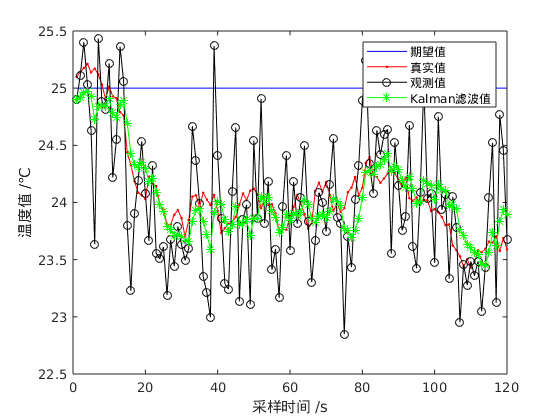

t = 1: N;
figure
plot(t, Xexpect, '-b', t, X, '-r.', t, Z, '-ko', t, Xkf, '-g*');
legend('期望值', '真实值', '观测值', 'Kalman滤波值');
xlabel('采样时间 /s');
ylabel('温度值 /℃');

误差分析

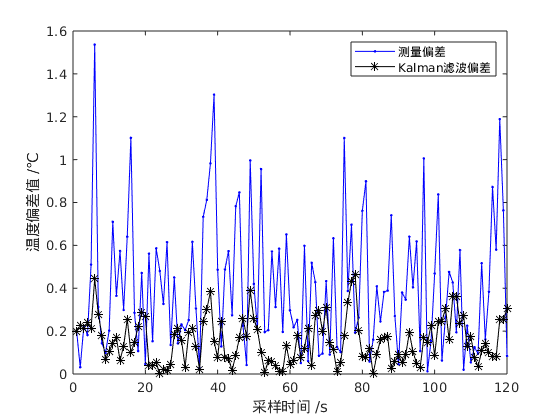

figure
plot(t, Err_Messure, '-b.', t, Err_Kalman, '-k*');
legend('测量偏差', 'Kalman滤波偏差');
xlabel('采样时间 /s');
ylabel('温度偏差值 /℃');